Kp = 1.12;
Ki = 0.232;
Kd = 0;
Ts = 0.1            %100ms

Ts = 0.1000

s1 = tf('s');

## funcion de transferencia del controlador


C = Kp + Ki/s1 + Kd*s1

C =
 
  1.12 s + 0.232
  --------------
        s
 
Continuous-time transfer function.



FUNCION DE TRANSFERENCIA DE LA PLANTA

Gp = 2.188/(10*s1+1)

Gp =
 
   2.188
  --------
  10 s + 1
 
Continuous-time transfer function.



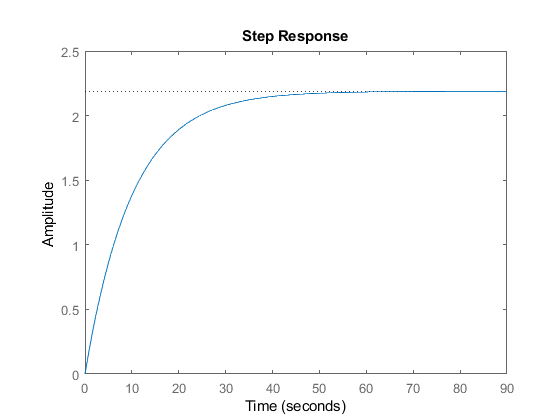

figure('Name','planta')
step(Gp)

## FUNCION DE TRANSFERENCIA DE LA PLANTA A LAZO CERRADO

GL = feedback(Gp,1)

GL =
 
     2.188
  ------------
  10 s + 3.188
 
Continuous-time transfer function.



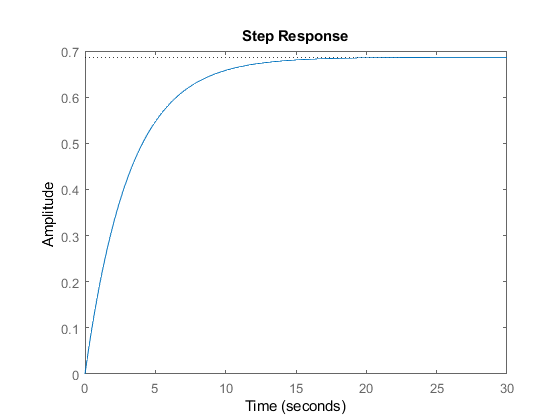

figure('Name','planta realimentado')
step(GL)

## FUNCION DE TRANSFERENCIA DE LA PLANTA CON EL PID


CG = series(C,Gp);
F = feedback(CG,1)

F =
 
      2.451 s + 0.5076
  -------------------------
  10 s^2 + 3.451 s + 0.5076
 
Continuous-time transfer function.



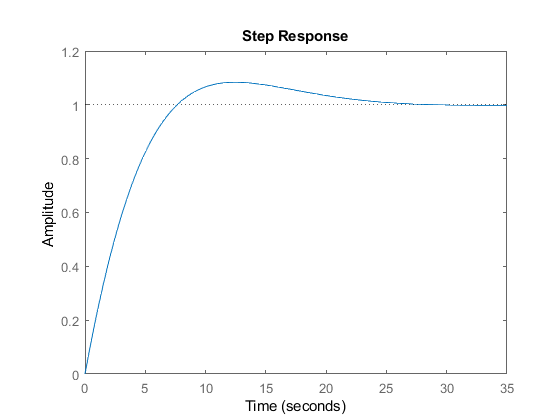

figure('Name','planta con controlador pid')
step(F)

## DISCRETIZACION

sysc = CG;
sysd = c2d(sysc,Ts,'zoh')

sysd =
 
  0.02464 z - 0.02413
  -------------------
  z^2 - 1.99 z + 0.99
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Fd = feedback(sysd,1)

Fd =
 
   0.02464 z - 0.02413
  ----------------------
  z^2 - 1.965 z + 0.9659
 
Sample time: 0.1 seconds
Discrete-time transfer function.



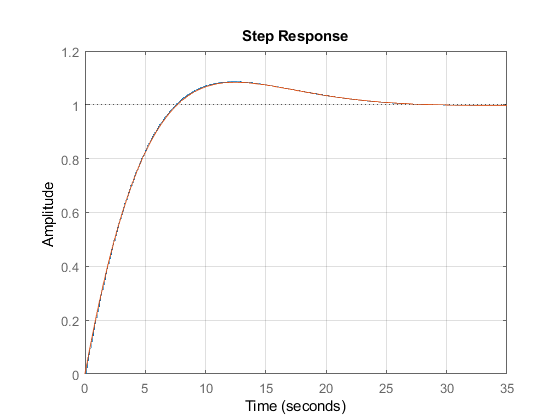

figure('Name','planta con controlador pid discretizado')
step(Fd)
hold on
step(F)
grid

## DISCRITAZACION DEL CONTROLADOR

Cd = c2d(C,Ts,'zoh')

Cd =
 
  1.12 z - 1.097
  --------------
      z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.

